clc
clear
fs=44100;
t=0:1/fs:0.5;
c4_2=key(60, 2, fs);  %make 12 semitones
cup4_2=key(61, 2, fs);
d4_2=key(62, 2, fs);
dup4_2=key(63, 2, fs);
e4_2=key(64, 2, fs);
f4_2=key(65, 2, fs);
fup4_2=key(66, 2, fs);
g4_2=key(67, 2, fs);
gup4_2=key(68, 2, fs);
a4_2=key(69, 2, fs);
aup4_2=key(70, 2, fs);
b4_2=key(71, 2, fs);
part1=[c4_2 cup4_2]; % Make two consecutive scales into a group
part2=[d4_2 dup4_2];
part3=[e4_2 f4_2];
part4=[fup4_2 g4_2];
part5=[gup4_2 a4_2];
part6=[aup4_2 b4_2]

part6 =          0    0.0664    0.1324    0.1979    0.2626    0.3260    0.3880    0.4484    0.5067    0.5628    0.6164    0.6673    0.7153    0.7601    0.8015    0.8394    0.8737    0.9040    0.9304    0.9527    0.9708    0.9845    0.9940    0.9991    0.9997    0.9960    0.9878    0.9754    0.9586    0.9375    0.9124    0.8832    0.8501    0.8133    0.7729    0.7291    0.6821    0.6320    0.5792    0.5238    0.4661    0.4064    0.3448    0.2818    0.2175    0.1522    0.0863    0.0200   -0.0464   -0.1126


legend1=[part1 part2 part3 part4 part5 part6];
sound(legend1,fs) % Play two consecutive scales
audiowrite('z.wav',legend1,fs);

[x,fs]=audioread('z.wav');
n = length(x);          % number of samples
f = (0:n-1)*(fs/n);
y = fft(x,n);
power = abs(y).^2/n;    % power of the DFT

plot(f(1:(n-1)/2),power(1:(n-1)/2))

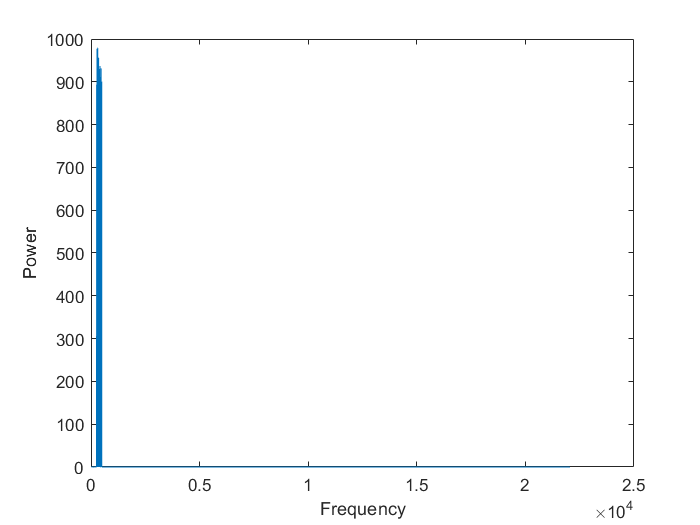

xlabel('Frequency')
ylabel('Power')

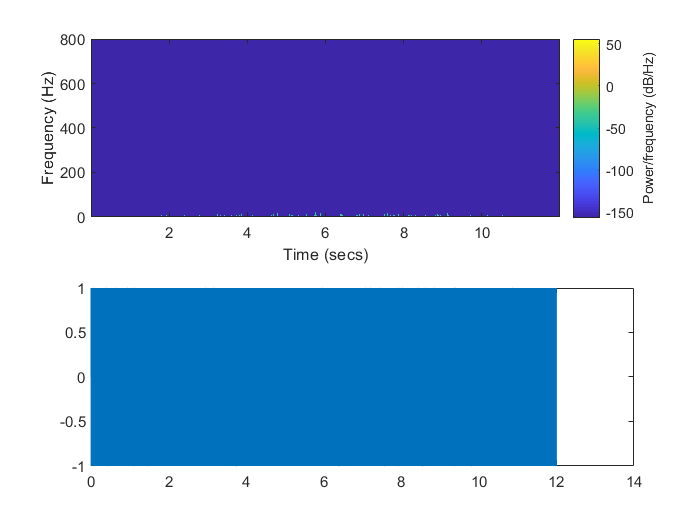


m=1:2:800;%设置频率刻度
subplot(2,1,1)
spectrogram(y,kaiser(128,18),120,m,fs,'reassigned','yaxis')
subplot(2,1,2)
wavEnergy=x(:,1);
time=(1/fs)*length(wavEnergy);
t=linspace(0,time,length(wavEnergy));
plot(t,wavEnergy);

function g=key(p, n, fs)
t=0 : 1/fs : 2/n;
g=sin(2*pi* fre(p) *t);
end
function f = fre(p)
f=440*2^((p-69)/12);
end
